%% Multi-Agent Traffic Simulation - MASTER VERSION (Live Heatmap)
% Features: 
% 1. Real-Time Dashboard with LIVE SPEED HEATMAP
% 2. Data Logging & Robust Physics
% 3. Crash Detection

clear; clc; close all;
yalmip('clear');

%% 1. CONFIGURATION SECTION

% -- Simulation Settings --
dt    = 0.1;          % Time step (s)
Tsim  = 60;           % Duration (s)
M     = 30;           % Total Number of Cars
L_track = 1000;       % Track Length (m)
R_track = L_track/(2*pi);

% -- Traffic Mix --
shuffle_mode = 1;   
pct_human = 0.9;      % 100% Humans (Maximum Chaos)
manual_order = [ones(1,10), 2*ones(1,20)]; 

% -- Speed Limits --
V_LIMIT_KMH = 130;    
V_LIMIT_MS  = V_LIMIT_KMH / 3.6; 
v_target_AV = V_LIMIT_MS;

% -- Human Behavior --
human_delay_time = 0.5; % Reaction delay (s)
delay_steps = round(human_delay_time / dt);
aggro_prob = 0.3;       % 30% Aggressive, 70% Inattentive

% -- Noise Parameters --
NOISE_STD = 0.3;        % Standard Deviation (m/s^2)

% -- Perturbation --
PERTURB_MODE = 1;       % 1 = Hard Brake Check
ID_PERTURBER = 1;       % Car 1 triggers it
PERTURB_TIME = 20.0;    % At t=20s

%% 2. INITIALIZATION

% A. Assign Driver Types
if shuffle_mode == 1
    types = [ones(1, round(M*(1-pct_human))), 2*ones(1, round(M*pct_human))];
    types = types(randperm(M)); 
else
    types = manual_order;
    M = length(types);
end

% B. Initialize Physics State
dist_init = L_track / M;
x_curr = zeros(M,1);
v_curr = ones(M,1) * (V_LIMIT_MS * 0.9); 
for i = 1:M, x_curr(i) = L_track - (i-1)*dist_init; end

% C. Initialize Human Memory Buffers
HistoryBuffer = cell(M,1);
for i = 1:M
    if types(i) == 2
        HistoryBuffer{i} = repmat([dist_init, v_curr(i), v_curr(i)], delay_steps+1, 1);
    end
end

% D. Assign IDM Parameters
HumanParams = struct();
for i = 1:M
    if types(i) == 2
        if rand() < aggro_prob
            % AGGRESSIVE
            HumanParams(i).v0 = (V_LIMIT_KMH + 15)/3.6; 
            HumanParams(i).T  = 0.8;   
            HumanParams(i).a  = 2.5;   
            HumanParams(i).b  = 3.0;   
            HumanParams(i).s0 = 2.0;   
            HumanParams(i).style = 'Aggressive';
        else
            % INATTENTIVE
            HumanParams(i).v0 = V_LIMIT_KMH/3.6; 
            HumanParams(i).T  = 1.2;   
            HumanParams(i).a  = 1.5;   
            HumanParams(i).b  = 2.0;   
            HumanParams(i).s0 = 4.0;   
            HumanParams(i).style = 'Inattentive';
        end
    end
end

%% 3. BUILD AV CONTROLLER (MPC)
fprintf('Building MPC Controller...\n');

Building MPC Controller...



N_hor = 20; 
w_traction=10; w_regen=2; w_v=5; w_d=20; w_s=10000;
amin=-9.0; amax=3.0; vmax=V_LIMIT_MS*1.3; vmin=0; smax=15; 
d0_av = 4.0; h_av = 1.2;

a_plus = sdpvar(N_hor,1); a_minus = sdpvar(N_hor,1);
v_opt = sdpvar(N_hor+1,1); p_opt = sdpvar(N_hor+1,1); s_opt = sdpvar(N_hor,1);
a_net = a_plus - a_minus;

p_init_var = sdpvar(1,1); v_init_var = sdpvar(1,1); p_lead_traj = sdpvar(N_hor+1,1);
v_ref_var   = sdpvar(1,1);

constraints = [p_opt(1)==p_init_var, v_opt(1)==v_init_var, amin<=a_net<=amax, ...
               vmin<=v_opt<=vmax, 0<=s_opt<=smax, a_plus>=0, a_minus>=0];
obj = 0;

for k = 1:N_hor
    constraints = [constraints, v_opt(k+1) == v_opt(k) + a_net(k)*dt];
    constraints = [constraints, p_opt(k+1) == p_opt(k) + v_opt(k)*dt + 0.5*a_net(k)*dt^2];
    constraints = [constraints, p_lead_traj(k+1) - p_opt(k+1) + s_opt(k) >= d0_av + h_av*v_opt(k+1)];
    
    obj = obj + w_traction*a_plus(k)^2 + w_regen*a_minus(k)^2 + ...
          w_v*(v_opt(k+1) - v_ref_var)^2 + w_s*s_opt(k)^2 + ...
          w_d*((p_lead_traj(k+1) - p_opt(k+1)) - (d0_av + h_av*v_opt(k+1)))^2;
end

AV_Controller = optimizer(constraints, obj, sdpsettings('solver','gurobi','verbose',0), ...
                          {p_init_var, v_init_var, p_lead_traj, v_ref_var}, a_net);

%% 4. DASHBOARD & LOGGING SETUP
scenario = drivingScenario;
scenario.SampleTime = dt;
scenario.StopTime = Tsim;

% -- Data Logging Pre-allocation --
N_steps = ceil(Tsim/dt);
step = 0;

% LIVE HEATMAP DATA STRUCTURE
% We fill this matrix column by column as time progresses
Live_Heatmap_Data = nan(M, N_steps); 

% -- Setup Figures --
hFig = figure('Position',[50 50 1400 900], 'Color', 'w');

% PANEL 1: 3D Simulation (Top Half)
hAx3D = subplot(2, 2, [1 2]); 
theta_road = linspace(0, 2*pi, 400)';
road_centers = [R_track*cos(theta_road), R_track*sin(theta_road), zeros(400,1)];
road(scenario, road_centers, 'Lanes', lanespec(1,'Width',12));
plot(scenario,'Parent',hAx3D);
view(hAx3D, 30, 60); axis(hAx3D,'equal'); grid(hAx3D,'on');
xlim(hAx3D,[-R_track-100 R_track+100]); ylim(hAx3D,[-R_track-100 R_track+100]);
title(hAx3D, 'Live Simulation');

% PANEL 2: Live Speed Heatmap (Bottom Left)
hAxSpeed = subplot(2, 2, 3);
% Create initial empty image
hHeatmapObj = imagesc(hAxSpeed, [0 Tsim], [1 M], Live_Heatmap_Data);
set(hAxSpeed, 'YDir', 'normal'); % Car 1 at bottom, M at top (or reverse if preferred)
colormap(hAxSpeed, jet);
c = colorbar(hAxSpeed); c.Label.String = 'Speed (m/s)';
clim(hAxSpeed, [0 V_LIMIT_MS]); % Fixed color scale
xlabel(hAxSpeed, 'Time (s)'); ylabel(hAxSpeed, 'Car ID');
title(hAxSpeed, 'Live Speed Heatmap');

% PANEL 3: Live Trajectories (Bottom Right)
hAxSpace = subplot(2, 2, 4);
hold(hAxSpace, 'on'); grid(hAxSpace, 'on');
title(hAxSpace, 'Live Trajectories');
xlabel(hAxSpace, 'Time (s)'); ylabel(hAxSpace, 'Position (m)');
xlim(hAxSpace, [0 Tsim]); ylim(hAxSpace, [0 L_track]);

% Create Animated Lines
lines = gobjects(M,1);
for i = 1:M
    if types(i) == 1, col = [0 0.8 0]; 
    elseif strcmp(HumanParams(i).style, 'Aggressive'), col = [1 0.5 0]; 
    else, col = [0 0 1]; end
    lines(i) = animatedline(hAxSpace, 'Color', col, 'LineWidth', 1.5);
end

% Create Visual Cars
adt_cars = cell(1,M);
VISUAL_SCALE = 3.5;
for i=1:M
    adt_cars{i} = vehicle(scenario, 'ClassID',1, 'Mesh',driving.scenario.carMesh, ...
        'Length', 4.5 * VISUAL_SCALE, 'Width', 2.0 * VISUAL_SCALE, 'Height', 1.6 * VISUAL_SCALE); 
end

%% 5. SIMULATION LOOP
fprintf('Starting Master Simulation...\n');

Starting Master Simulation...


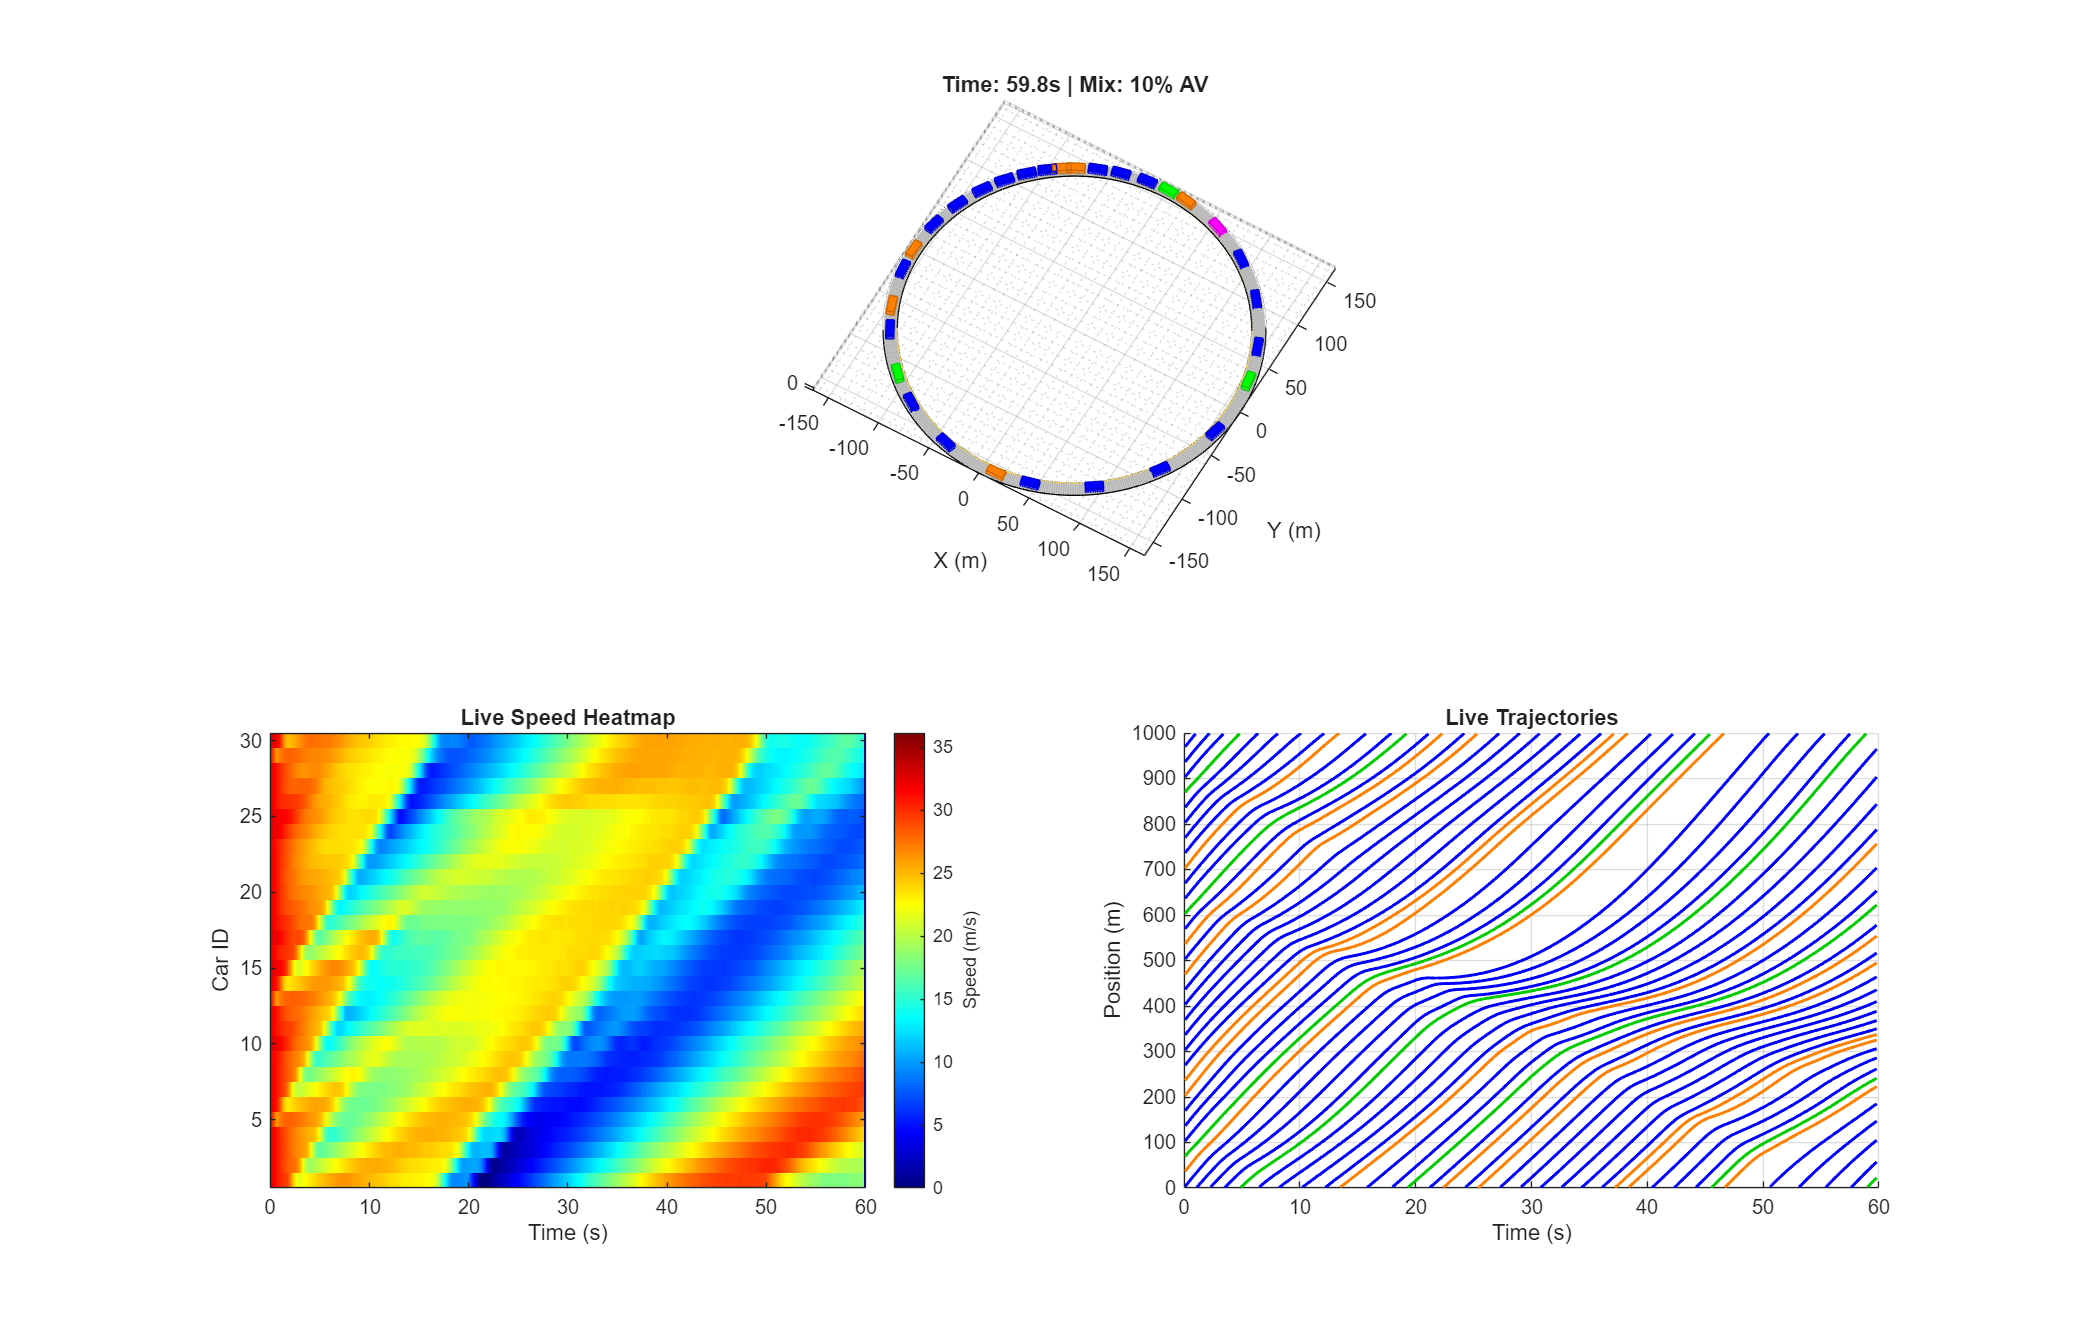

rate_limiter = rateControl((1/dt)); 

while advance(scenario)
    step = step + 1;
    t = scenario.SimulationTime;
    u_control = zeros(M,1);
    
    % --- Step A: Physics & Collision Check ---
    gaps = zeros(M,1);
    v_leads = zeros(M,1);
    crashed_idx = [];
    
    for i = 1:M
        if i == 1, id_lead = M; offset = L_track; else, id_lead = i-1; offset = 0; end
        pos_lead = x_curr(id_lead) + offset;
        gaps(i) = pos_lead - x_curr(i) - 4.5;
        v_leads(i) = v_curr(id_lead);
        if gaps(i) < 0, crashed_idx = [crashed_idx, i]; end
    end
    
    % --- Step B: Controls ---
    for i = 1:M
        if types(i) == 2 % HUMAN
             state_snapshot = [gaps(i), v_curr(i), v_leads(i)];
             HistoryBuffer{i} = [HistoryBuffer{i}(2:end, :); state_snapshot];
             delayed = HistoryBuffer{i}(1, :);
             s_del = delayed(1); v_del = delayed(2); vl_del = delayed(3);
             dv_del = v_del - vl_del;
             p = HumanParams(i);
             s_star = p.s0 + v_del*p.T + (v_del * dv_del) / (2 * sqrt(p.a * p.b));
             acc = p.a * (1 - (v_del/p.v0)^4 - (s_star/s_del)^2);
             acc = acc + NOISE_STD * randn();
             u_control(i) = max(amin, min(amax, acc));
        else % AV
             p_L_0 = x_curr(i) + gaps(i) + 4.5; 
             traj_L = p_L_0 + v_leads(i) * (0:N_hor)' * dt;
             inputs = {x_curr(i), v_curr(i), traj_L, v_target_AV};
             [sol, err] = AV_Controller(inputs);
             if err, u_control(i) = -4.0; else, val = sol(1); if isnan(val), val=0; end; u_control(i) = val; end
        end
    end
    
    % --- Step C: Perturbation ---
    if PERTURB_MODE == 1 && t > PERTURB_TIME && t < PERTURB_TIME + 2.0
        u_control(ID_PERTURBER) = -8.0; 
    end

    % --- Step D: Physics Update ---
    x_curr = x_curr + v_curr*dt + 0.5*u_control*dt^2;
    v_curr = max(0, v_curr + u_control*dt);
    
    % --- Step E: VISUALIZATION UPDATE ---
    
    % 1. Update 3D Cars (Same as before)
    for i = 1:M
        s_vis = mod(x_curr(i), L_track);
        theta = s_vis / R_track;
        adt_cars{i}.Position = [R_track*cos(theta), R_track*sin(theta), 0];
        adt_cars{i}.Yaw = (theta + pi/2) * (180/pi);
        
        if types(i) == 1, adt_cars{i}.PlotColor = [0 1 0]; 
        elseif strcmp(HumanParams(i).style, 'Aggressive'), adt_cars{i}.PlotColor = [1 0.5 0]; 
        else, adt_cars{i}.PlotColor = [0 0 1]; end
        
        if u_control(i) < -2.0, adt_cars{i}.PlotColor = [1 0 0]; end
        if i == ID_PERTURBER, adt_cars{i}.PlotColor = [1 0 1]; end
        if ismember(i, crashed_idx), adt_cars{i}.PlotColor = [0 0 0]; end
    end
    
    % 2. UPDATE LIVE HEATMAP
    if step <= N_steps
        % Store current speed in the column corresponding to this time step
        Live_Heatmap_Data(:, step) = v_curr;
        % Update the plot object (fast update)
        set(hHeatmapObj, 'CData', Live_Heatmap_Data);
    end
    
    % 3. Update Trajectories
    for i = 1:M
        s_val = mod(x_curr(i), L_track);
        [x_hist, y_hist] = getpoints(lines(i));
        if ~isempty(y_hist) && abs(s_val - y_hist(end)) > L_track/2
             addpoints(lines(i), t, NaN); 
        end
        addpoints(lines(i), t, s_val);
    end
    
    title(hAx3D, sprintf('Time: %.1fs | Mix: %.0f%% AV', t, (1-pct_human)*100));
    drawnow limitrate;
    waitfor(rate_limiter); 
    if ~ishandle(hFig), break; end
end


fprintf('Simulation Finished.\n');

Simulation Finished.
